close all;
clear all;
clc;

% Pior caso do sistema e com a carga nominal reduzida, entao projeto o
% controlador para carga de 10% para garantir o funcionamento do sistema 


% Reprojeto do controlador
s = tf('s');

% planta
potencia = 10 % 10%

potencia = 10

Vs = 50 % 50 V

Vs = 50

L = 12500e-6 % 12500uH

L = 0.0125

C = 50e-6 % 50uF

C = 5.0000e-05

R = 6.25 / (potencia/100) % 6.25 ohms -> (100% da potencia nominal)

R = 62.5000

Gvd = (Vs/(L*C)) / (s^2 + (1/(R*C))*s + (1/(L*C)))


Gvd =
 
          8e07
  --------------------
  s^2 + 320 s + 1.6e06
 
Continuous-time transfer function.



% filtro
H = 9.87e06 / (s^2 + 5441*s + 9.87e06)


H =
 
         9.87e06
  ----------------------
  s^2 + 5441 s + 9.87e06
 
Continuous-time transfer function.



% Controlador
% quero uma resposta sem sobresinal (dinamica dominante de primeira ordem), sem erro em regime permanente e com
% tempo de acomodaçao de aproximandamente 1ms para uma entrada degrau
C = 1/s % -> controlador puramente integrador coloca um polo em 0 -> erro nulo em regime permanente


C =
 
  1
  -
  s
 
Continuous-time transfer function.


% como estou fazendo um PI preciso colocar um zero 
% usando o control system designer do matlab
% posiçao do zero foi escolhido para dar uma boa margem de escolha de ganho
% com o sistema mantendo estavel
% coloquei um zero em -6.5e5 e mudei a posiçao do polo de malha fechada mudando o ganho para
% atender o requisito de tempo de acomodaçao de 0.04s e da respsota
% aproximada de primeira ordem
% sistema com dinamica dominante de primeira ordem -> tempo de assentamneto
% = 4/a com a sendo a distancia do polo dominante segundo ogata
% 1ms = 4/a -> a = 4/1ms -> a = -4000  \cite{Ogata2009-pa}
a = 4/0.02

a = 200

s0 = -a;
K = 1 / abs(evalfr(((s + 6.5e5)/s) * Gvd * H, s0))

K = 5.4195e-06


Cp =  (K * (s+6.5e5)) / s


Cp =
 
  5.419e-06 s + 3.523
  -------------------
           s
 
Continuous-time transfer function.


T = feedback(Gvd * Cp, H)


T =
 
           433.6 s^3 + 2.842e08 s^2 + 1.538e12 s + 2.781e15
  -------------------------------------------------------------------
  s^5 + 5761 s^4 + 1.321e07 s^3 + 1.186e10 s^2 + 1.58e13 s + 2.781e15
 
Continuous-time transfer function.


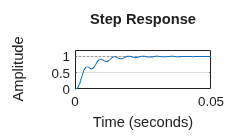


figure;
step(T);
grid on